# ICA Testing

subjectNames = {
    'mitdb/100';
    'mitdb/101';
    'mitdb/102';
    'mitdb/103';
    'mitdb/104';
    'mitdb/105';
    'mitdb/106';
    'mitdb/107';
    'mitdb/108';
    'mitdb/109';
    'mitdb/111';
    'mitdb/113';
    'mitdb/114';
    'mitdb/115';
    'mitdb/116';
    'mitdb/117';
    'mitdb/118';
    'mitdb/119';
    'mitdb/121';
    'mitdb/122';
    'mitdb/123';
    'mitdb/124';
    'nstdb/118e_6';
    };
%set number of files
files = length(subjectNames);
%Initialize Arrays
Fs = zeros(files,1);
ecg = cell(files,1);
tm = cell(files,1);
rr = cell(files,1);
rr_tm = cell(files,1);
%loop through all file names
for fi = 1:files
    [ecg{fi,1},Fs(fi),tm{fi,1}]= rdsamp(subjectNames{fi,1},1);
    [rr{fi,1},rr_tm{fi,1}]=ann2rr(subjectNames{fi,1},'atr');
end 
%Note: Noise was added beginning after the first 5 minutes of each record, during two-minute segments alternating with two-minute clean segments.
file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
%Split into 10s segments
sec_per_seg = 1; 
segs = floor(n/(fs*sec_per_seg));
data = data(1:segs*fs*sec_per_seg); 
data_ar = reshape(data,[fs*sec_per_seg,segs]);
data_ar = data_ar';

## First Attempt at ICA

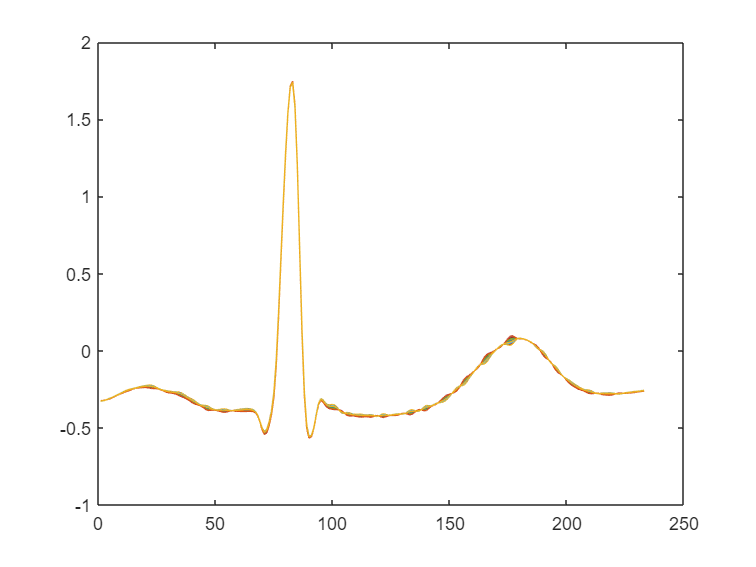

file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
this_rr = rr{file_idx,1};
this_tm = rr_tm{file_idx,1};
%Split into segments by peaks
samp_per_seg = min(this_rr);
segs = length(this_rr); 
data_ar = [];

for i = 2:length(this_tm)
    t = this_tm(i);
    data_row = data(t-80:t+samp_per_seg-81)'; 
    data_ar = [data_ar; data_row];
end 
%plot(data_ar(360:390,:)'); testing same data as PCA example

% Compute the ICA transformation
% Transpose data_ar because kICA expects samples as columns
[Zica, W, T, mu] = kICA(data_ar', 1); % We compute only 1 IC as an example

% Reconstruct the signal using the selected independent components
% Zica is r x n, W is d x n, and we need only the first component
reconstructed_signal = T \ (W(:,1) * Zica(1,:));
reconstructed_signal = reconstructed_signal' + mu'; % Add the mean back to the data

% Plot the reconstructed signal for the same segments as before
plot(reconstructed_signal(360:390,:)');

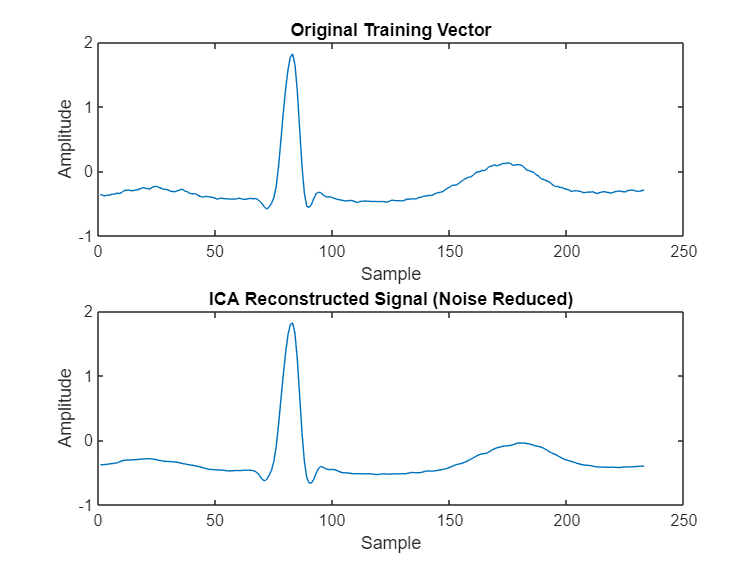


numComponents = 10; % Example number of initial components
[Zica, W, T, mu] = kICA(data_ar', numComponents);

% Optionally, plot each component for visual inspection
%for i = 1:numComponents
%    reconstructed_signal = T \ (W(:,i) * Zica(i,:));
%    reconstructed_signal = reconstructed_signal' + mu'; % Add the mean back to the data
%    figure; % Open a new figure window for each plot
%    plot(reconstructed_signal);
%    title(['Independent Component ', num2str(i)]);
%end

% Assuming kICA function is defined and available
numComponents = 30;  % Choosing 30 components; adjust based on your needs
[Zica, W, T, mu] = kICA(data_ar', numComponents);

% Analyze components and decide which to drop (manually or automatically)
% For this example, let's assume we decide to drop components that are likely noise
% This could be based on statistical analysis like kurtosis, power, etc.

% Calculate kurtosis for each component
componentKurtosis = real(kurtosis(Zica'));

% Assume noise components have very high kurtosis
thresholdKurtosis = prctile(componentKurtosis,85); % Adjust threshold as needed
noiseIndicesKurt = find(componentKurtosis > thresholdKurtosis);

% Exclude noise components and reconstruct the signal
Zica(noiseIndicesKurt, :) = 0;  % Zero out noise components
% Select first 30 components from W and the corresponding scores from Zica
W_30 = W(:, 1:30);       % Dimension [5400 x 30]
Zica_30 = Zica(1:30, :); % Dimension [30 x 1122]

% Matrix multiplication
% Zica_30 is already appropriately oriented for multiplication with W_30
component_data = W_30 * Zica_30;  % Resulting dimension [5400 x 1122]

% Applying the inverse transformation using T
reconstructed_train = T \ component_data;  % Dimension [5400 x 1122]

reconstructed_train = reconstructed_train' + mu';  % Add mean back

% Visualizing one of the reconstructed signals compared to the original
test_idx = 3;  % Index of the example to plot
original_signal = data_ar(test_idx, :);
reconstructed_signal = reconstructed_train(test_idx, :);

figure;
subplot(2,1,1);
plot(original_signal);
title('Original Training Vector');
xlabel('Sample');
ylabel('Amplitude');

subplot(2,1,2);
plot(reconstructed_signal);
title('ICA Reconstructed Signal (Noise Reduced)');
xlabel('Sample');
ylabel('Amplitude');

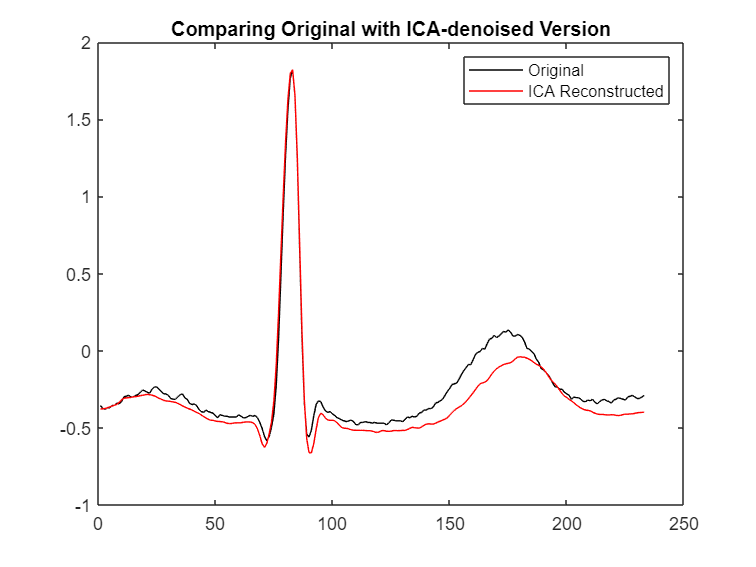


% Comparison plot
figure;
plot(original_signal, 'k');
hold on;
plot(reconstructed_signal, 'r');
legend('Original', 'ICA Reconstructed');
title('Comparing Original with ICA-denoised Version');